Constants

syms a b real
assumeAlso(a > 0 & b > 0)

State variables

syms x y real
s = [x;y];

State equations

dx = a + x^2*y - b*x - x;
dy = -x^2*y + b*x;
f = [dx;dy];

sol = solve(f)

sol = struct with fields:
    x: a
    y: b/a


Eq = [sol.x ; sol.y]

$$Eq = \left(\begin{array}{c} a\\ \frac{b}{a} \end{array}\right)$$

The fixed point becomes unstable when $b > 1 + a^2$.

J = jacobian(f,s)

$$J = \left(\begin{array}{cc} 2\,x\,y-b-1 & x^{2}\\ b-2\,x\,y & -x^{2} \end{array}\right)$$

A = subs(J,s,Eq)

$$A = \left(\begin{array}{cc} b-1 & a^{2}\\ -b & -a^{2} \end{array}\right)$$

syms lambda real
collect(det(eye(2)*lambda - A),lambda)

$$ans = \lambda^{2}+\left(a^{2}-b+1\right)\,\lambda +a^{2}$$

lambda = simplify(eig(A))

$$lambda = \left(\begin{array}{c} \frac{b}{2}-\frac{\sqrt{-\left(-a^{2}+2\,a+b-1\right)\,\left(a^{2}+2\,a-b+1\right)}}{2}-\frac{a^{2}}{2}-\frac{1}{2}\\ \frac{b}{2}+\frac{\sqrt{-\left(-a^{2}+2\,a+b-1\right)\,\left(a^{2}+2\,a-b+1\right)}}{2}-\frac{a^{2}}{2}-\frac{1}{2} \end{array}\right)$$

lambda2_fh = matlabFunction(lambda(2))

lambda2_fh = function_handle with value:
    @(a,b)b./2.0+sqrt(-(a.*2.0+b-a.^2-1.0).*(a.*2.0-b+a.^2+1.0))./2.0-a.^2./2.0-1.0./2.0


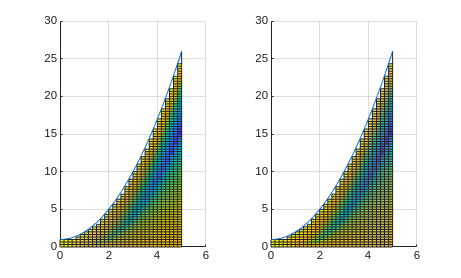

lambda2_val = lambda2_fh(aa,bb);
lambda2_val(real(lambda2_val) > 0) = nan;
Tl = tiledlayout(1,2);
nexttile,
surf(aa,bb,real(lambda2_val)), hold on
fplot(@(a) 1 + a.^2,[0 5])
view([0,90])
nexttile
surf(aa,bb,real(lambda2_val)), hold on
fplot(@(a) 1 + a.^2,[0 5])
view([0,90])

Numerical values

a = 1;
b = 3;
f_ode = matlabFunction(subs(f),'Vars',{sym('t'),s});

s0 = [a;b/a]*1.001;
[tt,xx] = ode89(f_ode,[0 40],s0);

f1_fh = matlabFunction(subs(f(1)));
f2_fh = matlabFunction(subs(f(2)));

[xMesh, yMesh] = meshgrid(linspace(0,5,301));

ff1 = f1_fh(xMesh,yMesh);
ff2 = f2_fh(xMesh,yMesh);

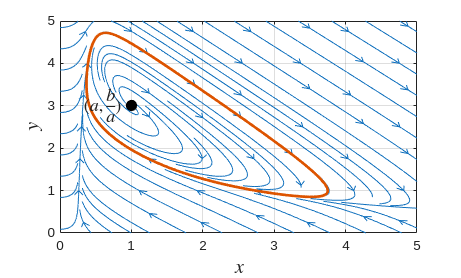

fig = figure(31);
Tl = tiledlayout(1,1);
hold on, box on, grid on;

streamslice(xMesh,yMesh,ff1,ff2);

ldx = tt > 30;
plot(xx(ldx,1),xx(ldx,2),'LineWidth',2)
Eq_ = double(subs(Eq));
plot(Eq_(1),Eq_(2),'k.','MarkerSize',25)
text(Eq_(1),Eq_(2),'$(a,\frac{b}{a})~~$','Interpreter','latex','FontSize',13,'HorizontalAlignment','right')
xlabel('$x$','Interpreter','latex','FontSize',15);
ylabel('$y$','Interpreter','latex','FontSize',15);

$$f = \left(\begin{array}{c} a-x-b\,x+x^{2}\,y\\ b\,x-x^{2}\,y \end{array}\right)$$

exportgraphics(fig,'/home/ppolcz/Dropbox/Peti/PhD/Oktatas/11_NDS/2025/Tematika/fig/Brusselator_LC.pdf','ContentType','vector');